%6 nodes along each row
n = 6;
nOnes = ones(n,1);
T = diag(4*nOnes,0) + diag(-1*nOnes(1:n-1), -1) + diag(-1*nOnes(1:n-1),1);
I = -1*eye(6);
Z = zeros(6,6);
A = [T I Z Z Z Z; I T I Z Z Z; Z I T I Z Z; Z Z I T I Z; Z Z Z I T I; Z Z Z Z I T];
b = [0; 0; 0; 0; 0; 40; 0; 0; 0; 0; 0; 40; 0; 0; 0; 0; 0; 40; 0; 0; 0; 0; 0; (4/3) + 40; 0; 0; 0; 0; 8/3; 70; 70; 70; 70 + 4/3];

%make changes for insulated boundary
A(1,1) = 2;
A(2,2) = 3;
A(3,3) = 3;
A(4,4) = 3;
A(5,5) = 3;
A(6,6) = 3;

A(7,7) = 3;
A(13,13) = 3;
A(19,19) = 3;
A(25,25) = 3;
A(31,31) = 3;

%changes along convective boundary
A(24,24) = (4+0.2/3);
A(29,29) = (4+0.4/3);
A(34,34) = (4+0.2/3);

%nothing should rely on u(4,5) which is row and column 30
A(:,30) = [];
A(30,:) = [];
%same for columns/rows 35 and 36 (but because we've already deleted
%values, they're now rows 34 then 34 again)
A(:,34) = [];
A(34,:) = [];
A(:,34) = [];
A(34,:) = [];

%RCM Storage
%Create a new A matrix to work with
A_RCM = A;
%create ordering vector
p= symrcm(A_RCM);
%order the A matrix and b vector according the RCM storage
A_RCM = A_RCM(p,p);
b_rcm = b(p);
reorder = reorder_vector(p);
%factorise the A matrix with cholesky factorisation
A_RCM = cholesky(A_RCM);
%solve with forward substitution and then backwards substitution

temperatures = forward_substitution(A_RCM', b_rcm);
temperatures = backward_substitution(A_RCM, temperatures);
temperatures = temperatures(reorder);

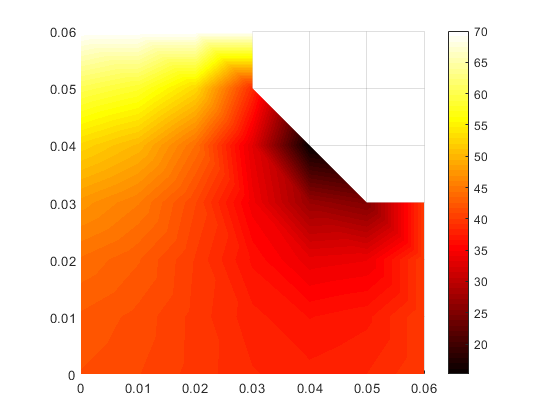



%visualisation framework

%temperatures = A\b;
[X, Y] = meshgrid(0:0.01:0.06, 0:0.01:0.06);
%create rectangular mesh
Temps = zeros(7,7);

Temps(1,1:6) = temperatures(1:6);
Temps(1,7) = 40;
Temps(2,1:6) = temperatures(7:12);
Temps(2,7) = 40;
Temps(3,1:6) = temperatures(13:18);
Temps(3,7) = 40;
Temps(4,1:6) = temperatures(19:24);
Temps(4,7) = 40;
Temps(5,1:5) = temperatures(25:29);
Temps(6,1:4) = temperatures(30:33);
Temps(5,6:7) = nan;
Temps(6,5:7) = nan;
Temps(7,5:7) = nan;
Temps(7,1:4) = 70;



temperatures = Temps(~isnan(Temps));

x = X(~isnan(Temps));
y = Y(~isnan(Temps));

tri = delaunay(x, y);


tri(44,:) =[];
tri(43,:) =[];
tri(42,:) =[];



figure;
trisurf(tri, x, y, temperatures)
view(2)
shading interp
colormap hot
colorbar
axis image